robot = importrobot("robot.urdf");
q = homeConfiguration(robot);
dof = length(q);

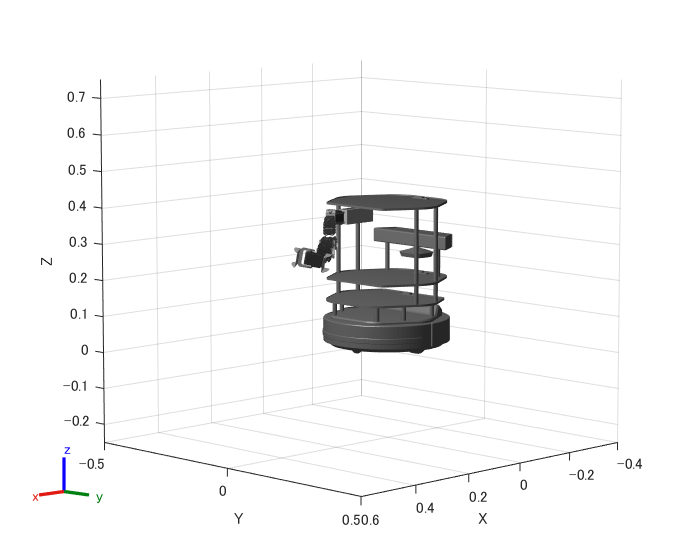

% q(1) -> y+
q(1).JointPosition = deg2rad(40);
% q(2) -> 正面から見て反時計回り
q(2).JointPosition = deg2rad(0);
% q(3) -> z+
q(3).JointPosition = deg2rad(0);
% q(4) -> 正面から見て反時計回り  実機では逆！！！
q(4).JointPosition = deg2rad(0);
% q(5) -> z+
q(5).JointPosition = deg2rad(0);
% q(6) -> 正面から見て反時計回り  実機では逆！！！
q(6).JointPosition = deg2rad(-10);
% q(7) -> +で開く -50くらいで閉じる
q(7).JointPosition = deg2rad(0);
show(robot, q, Frames="off");
xlim([-0.4 0.6])
ylim([-0.5 0.5])
zlim([-0.25 0.75])